The experiment consisted of a circular trajectory and arm deployment. This was to validate the new laboratory software as well as to test the added sensors. First we load the data.

RED = load('RED_Data.mat');
BLACK = load('BLACK_Data.mat');

Now we plot the attitude from the IMU and PhaseSpace for the RED platform.

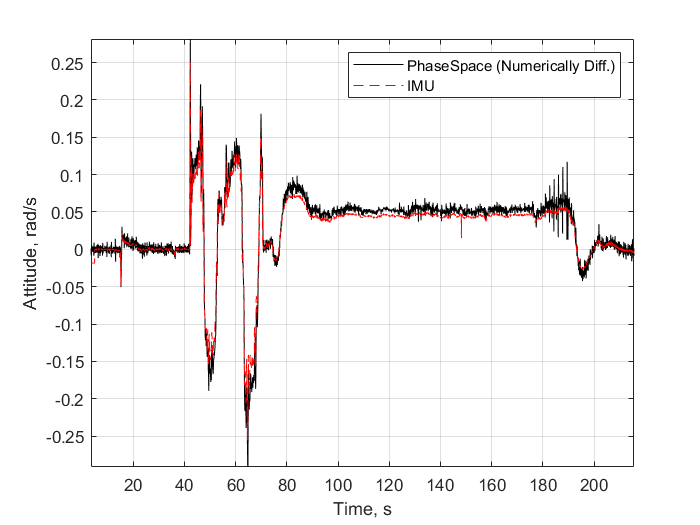

figure()
plot(RED.rt_dataPacket(100:end,1), RED.rt_dataPacket(100:end,10),'-k')
hold on
grid on
axis tight
plot(RED.rt_dataPacket(100:end,1), RED.rt_dataPacket(100:end,43),'--r')
xlabel('Time, s')
ylabel('Attitude, rad/s')
legend('PhaseSpace (Numerically Diff.)','IMU','location','northeast')

Now for the BLACK platform.

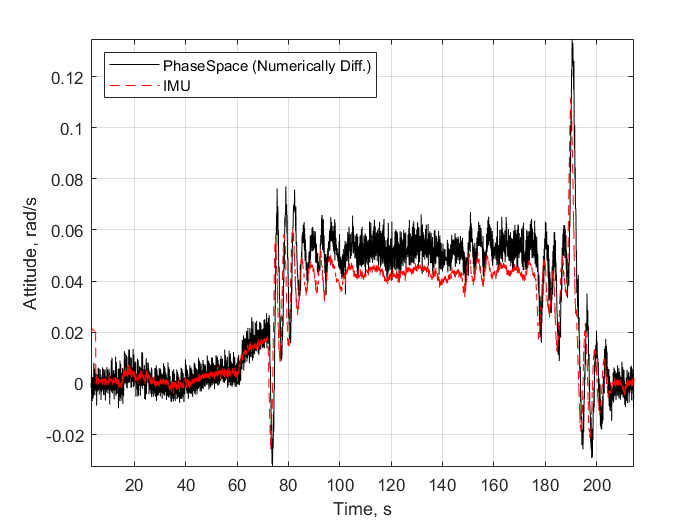

figure()
plot(BLACK.rt_dataPacket(100:end,1), BLACK.rt_dataPacket(100:end,25),'-k')
hold on
grid on
axis tight
plot(BLACK.rt_dataPacket(100:end,1), BLACK.rt_dataPacket(100:end,46),'--r')
xlabel('Time, s')
ylabel('Attitude, rad/s')
legend('PhaseSpace (Numerically Diff.)','IMU','location','northwest')

Evidently there are some differences here. It is recommended that a Kalman Filter be implemented.